依赖[统一实验分析作图v17.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

DataSet=TransferLearning.FullCalcium;
QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'统一PCA');
Calcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(QueryTable,UniExp.Flags.log2FdF0,1:24,UniExp.Flags.Median));

PcaTable=UniExp.LinearPca(Calcium.NTATS,6);

选出声光细胞

ALCells=DataSet.TableQuery("CellUID",CellUID=Calcium.CellUID,Paradigm="声光").CellUID;
Logical=ismember(Calcium.CellUID,ALCells);
ALScore=pagemtimes(PcaTable.Coeff(:,Logical),Calcium.NTATS{Logical,:,["Learned","Transfer_hit","Transfer_miss"]});

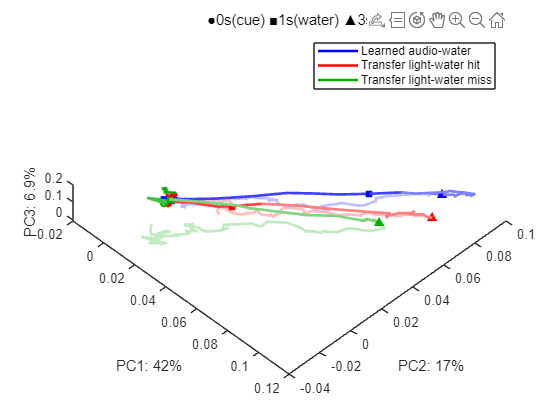

PCs=1:3;
PcaScore=permute(ALScore(PCs,:,:),[3,1,2]);
LinesPC=table;
LinesPC.Points=PcaScore;
LinesPC.Color=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Markers=table;
Markers.Index=[24;32;48];
Markers.Shape=('os^')';
figure;
Lines=UniExp.SegmentFadePlot(LinesPC,Markers,PatchArguments={'LineWidth',2});
UniExp.PcAxLabels(table(PCs',PcaTable.Explained(PCs),'VariableNames',["Index","Explained"],'RowNames',["X";"Y";"Z"]));
legend(Lines,["Learned audio-water","Transfer light-water hit","Transfer light-water miss"],Interpreter='none',Location='northeast');
title('●0s(cue) ■1s(water) ▲3s');
Explained=PcaTable.Explained(PCs);
view(45,90*(1-Explained(3)/sum(Explained)));
%3D无法生成矢量图，只能点阵
print(TransferLearning.ProjectPath('AudioLightPca.png'),'-dpng','-r200');